**Given: **

%Measurement L, Error Free X,  Function Model

**Wanted:   Solved by Matrix Computation**

%Unknown X, Residual
addpath Function\
addpath Data\

**Write Function Model**

% ---------------------------------
% Define your Measurement L and unknow
% ---------------------------------
% 1.Measurement L
syms L_ [3 1]
L_=L_;
% 2.Error Free
syms X [5 1]       
% 3.Unknow X
syms x y
X_=[x;y];   %  Only use ;
% 4. Constraint
syms LB_ [1 1]
LB_=[LB_;];

% 4.Function Model
L_dash_=L_+0;
F_=[x+y-2*y^2
    x^2+ y^2
    3*x^2-y^2];
FB_=[x^3+y^(1/3)];
disp("=========================")

disp("Function Model") 

Function Model


disp("=========================")

L_dash_==F_;
disp("=========================")

disp("Constraint Model") 

Constraint Model


disp("=========================")

LB_==FB_;

% Observation Equation
disp("=========================")

disp("Observation Equation") 

Observation Equation


disp("=========================")

V_=F_-L_dash_;

% Get Design Matrix
A_=jacobian(V_,X_);

if exist("FB_","var")
    B_=jacobian(FB_,X_);
end

**Measurement and Redundancy**

% 6.Measurement L
Ndeal(L_, [-4 8 7.7]')
% 7.Free Error X
Ndeal(X, [1 1 1 1 1])
% 8.Initial values for the unknowns
x=2; y=2;
% 9.Constraint
Ndeal(LB_, [9]')

%Number of observations
no_n =  length(L_dash_);
%Number of unknowns
no_u = length(X_);
%constraint
no_b=length(FB_);
%Redundancy
r = no_n-no_u+no_b;

**Set up Stochastic Model  **

%% 6. Sigma  
s_dis=1;   
s_dis=ones(length(L_),1)*(s_dis)^2;      
%s_dir_g=0.001;
%s_dir_g=ones(length(Dir),1)*(s_dir_g*pi/200)^2;  %gon to rad
S_LL = diag(s_dis);

%Theoretical reference standard deviation
sigma_0 =1;
%Cofactor matrix of the observations
Q_LL = 1/sigma_0^2*S_LL;
%Weight matrix
P_LL = inv(Q_LL); 

 

**Adjustment**

 
L_0=eval(L_);
V_0=eval(V_);
L_dash_0=eval(L_dash_);
X_0=eval(X_);
L_dash_hat=eval(L_dash_);

%break-off conditions
epsilon = 10^-5;
delta = 1e-9;
iteration = 0;
max_xsmall_hat=10^Inf;

while  max_xsmall_hat>epsilon || max(abs(L_dash_hat-eval(F_)))>delta
     
    iteration=iteration+1;
    A_evl=eval(A_);
    B_evl=eval(B_);
    l_vec=L_dash_0-eval(F_); % vector of reduced observation
    
    %Normal matrix
    N = A_evl'*P_LL* A_evl;  
    N_ext=[N B_evl';B_evl 0];
    %Vector of right hand side of normal equations
    n = A_evl'*P_LL*l_vec;
    n_ext = [n;eval(LB_)-eval(FB_)];
    %Inversion of normal matrix / Cofactor matrix of the unknowns
    Q_xx_ext = inv(N_ext);
    Q_XX = Q_xx_ext(1:no_u,1:no_u);    
    %Solution of normal equation
    X_smallhat=Q_xx_ext*n_ext;     
    
    % Update v
    max_xsmall_hat=max(abs(X_smallhat(1:no_u)));
    V_hat = A_evl*X_smallhat(1:no_u)-l_vec;
    %
    Ndeal(X_,X_smallhat(1:no_u)+eval(X_));
    Ndeal(L_,L_0+V_hat);
    L_dash_hat = L_dash_0+V_hat;
    L_hat=L_0+V_hat;
    X_hat=eval(X_);
    
    %Objective function
    vTPv = V_hat'*P_LL*V_hat;
    if iteration > 300
        error("Wrong")
    end
end

%Final check
if abs(L_dash_hat-eval(F_))<delta
    disp("Good")
else
    disp("Wrong")
end

Good


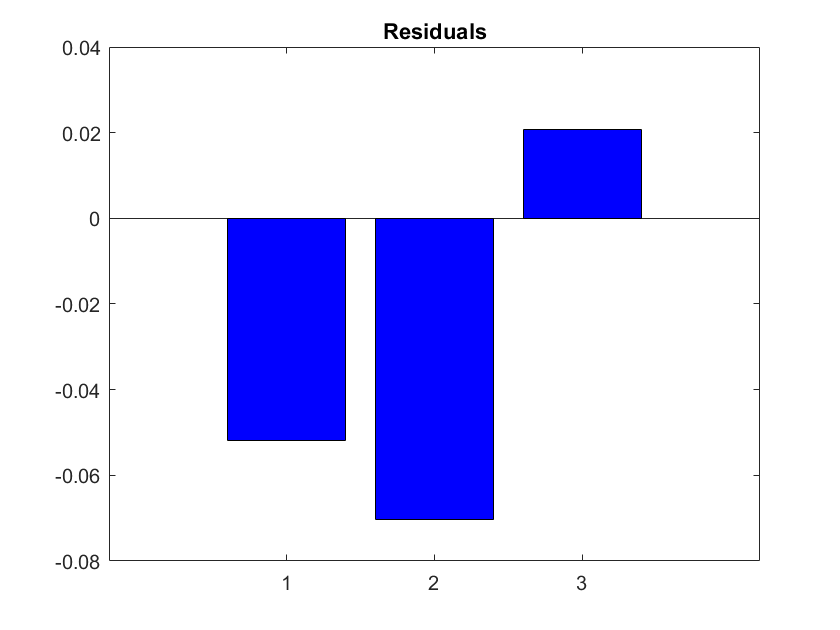


%plotxyc(X,L_dash,eval(F_))
figure
bar(V_hat,"b")
title("Residuals")


%Empirical reference standard deviation
s_0 = sqrt(vTPv/(r));     %a posteriori
%VC matrix of adjusted unknowns
S_XX_hat = s_0^2*Q_XX;
%Cofactor matrix of adjusted observations
Q_LL_hat = A_evl*Q_XX*A_evl';
%VC matrix of adjusted observations
S_LL_hat = s_0^2*Q_LL_hat;
%Cofactor matrix of the residuals
Q_vv = Q_LL-Q_LL_hat;
%VC matrix of residuals
S_vv = s_0^2*Q_vv;

S_v=sqrt(diag(S_vv));
S_X=sqrt(diag(S_XX_hat));
S_L=sqrt(diag(S_LL_hat));

**Get Result**

%Conversion
%L_i=length(D):length(D)+length(Dir); 
%X_i=length([X;Y]):length([X;Y])+length(w);
%L_hat(L_i)=L_hat(L_i)*200/pi;
%S_L(L_i)=S_L(L_i)*200/pi;
%X_hat(X_i)=X_hat(X_i)*200/pi;
%S_X(X_i)=S_X(X_i)*200/pi;
%V_hat(L_i)=V_hat(L_i)*200/pi;
%S_v(L_i)=S_v(L_i)*200/pi;

disp("=========================")

disp("Get Result and S_xx") 

Get Result and S_xx


disp("=========================")

format long


disp("Get Unknown X_hat, S_x:") 

Get Unknown X_hat, S_x:


Unknown=arrayfun(@(x) sprintf("%s",x),X_);
table(Unknown,X_hat,S_X)

ans = 2×3 table
    Unknown         X_hat                  S_X         
    _______    ________________    ____________________

      "x"       1.9780249039086    0.000124663487465504
      "y"      2.00425702618708     0.00697826696141915



disp("Get Updated L_hat, S_l:") 

Get Updated L_hat, S_l:


Measurment=arrayfun(@(x) sprintf("%s",x),L_);
table(Measurment,L_0,L_hat,L_dash_hat,S_L,["V_"+(1:length(V_hat))'],V_hat,S_v)

ans = 3×8 table
    Measurment    L_0          L_hat             L_dash_hat               S_L            Var6            V_hat                  S_v        
    __________    ___    _________________    _________________    __________________    _____    ___________________    __________________

      "L_1"        -4    -4.05181052394487    -4.05181052394487    0.0490913586161212    "V_1"    -0.0518105239448738    0.0402806767258352
      "L_2"         8     7.92962874750291     7.92962874750291     0.027479306072162    "V_2"    -0.0703712524970911    0.0572484248347525
      "L_3"       7.7     7.72070133442762     7.72070133442762    0.0294520059636637    "V_3"      0.020701334427617    0.0562589881973021




eval(LB_)

ans =      9


eval(FB_)

ans =    9.000000000000004
